First, follow the installation instructions in README.md and add mesolf code folder to path, including all subfolders.

Set MesoLF parameters

workdir = pwd();  % change to desired working directory
if ~exist(workdir, 'dir')
    mkdir(workdir);
end
SIin = struct;
% SIin.indir = [workdir filesep() '20220614_mouse2_exp2'];
SIin.indir = '/home/jose/big_data/Light_Field_Microscope/li_et_al_code/SIsoftware/Data/01_Raw/20220614_mouse2_exp2/';
SIin.outdir = [workdir filesep() 'mesolf_mouse2_frames1to2400'];
SIin.frames_start = 1;
SIin.frames_step = 1;
SIin.frames_end = 2400;
SIin.frameRate = 20;
SIin.frames_average = false;
SIin.frames_x_offset = 1040.0;
SIin.frames_y_offset = 1036.0;
SIin.frames_dx = 31.2;
SIin.frames_crop_border_microlenses = [1 1 1 1];
SIin.mask_file = false;  % don't mask out anything, all is valid
SIin.patch_mode = 'carpet';
% SIin.n_patches = [2 2];  % 2 x 2 tiles
SIin.n_patches = [1 1];  % 1x1
SIin.psffile = fullfile(workdir, 'PSFmatrix_M10NA0.5MLPitch125fml1250from-50to50zspacing2Nnum31lambda520n1.0.mat');  % will be downloaded in next section
SIin.gpu_ids = 1;  % select high-performance GPU here; indices start at 1 (so, add one to the gpu indices reported by nvidia-smi, which start at 0)
SIin.filt_method = 'cnn';
% Added by Jose
SIin.reg_flag = false; % Registration
SIin.reg_bin_width = 100;
SIin.valid_recon_range = 51; % Requires integer type
% SIin.neuron_lateral_size = 75; %

Download & unzip PSF file (3.3 GB) and raw data (17.5 GB). Demo dataset are two tiles (sub-ROIs) of the data shown in Fig. 2a (0-200 um depth range)

% psf_fullpath = websave(SIin.psffile, ...
%     'https://zenodo.org/record/7306113/files/PSFmatrix_lfm2pram_M10_FN12p5_pm200_from-200_to200_zspacing4_Nnum15_lambda520_OSR3.mat?download=1');

Error using matlab.internal.webservices.HTTPConnector/copyContentToFile
Web service operation terminated by user while accessing URL 'https://zenodo.org/record/7306113/files/PSFmatrix_lfm2pram_M10_FN12p5_pm200_from-200_to200_zspacing4_Nnum15_lambda520_OSR3.mat?download=1'.

Error in websave (line 107)
copyContentToFile(connection, filename);

% rawzip_fullpath = websave(fullfile(workdir, 'mesolf_demo_dset.zip'), ...
%     'https://zenodo.org/record/7306113/files/mesolf_demo_dset.zip?download=1');
% unzip(rawzip_fullpath, SIin.indir);


Configure cluster pool here - HPC only

% c = parcluster;
% c.AdditionalProperties.QueueName='gpu';
% c.AdditionalProperties.MemUsage = '128gb'

c = 

 Generic Cluster

    Properties: 

                   Profile: cluster R2022a
                  Modified: false
                      Host: jmorenolar.hpc.einsteinmed.edu
                NumWorkers: 1000
                NumThreads: 1

        JobStorageLocation: /gs/gsfs0/users/jmorenolar/.matlab/3p_cluster_jobs/cluster/R2022a/shared
         ClusterMatlabRoot: /gs/gsfs0/hpc01/rhel8/apps/MATLAB/R2023a
           OperatingSystem: unix

   RequiresOnlineLicensing: false
   PreferredPoolNumWorkers: 32
     PluginScriptsLocation: /gs/gsfs0/hpc01/rhel8/apps/MATLAB/support_packages/matlab_parallel_server/scripts/IntegrationScripts/cluster
      AdditionalProperties: 

% c.AdditionalProperties.GpusPerNode = 2;
% c.AdditionalProperties.ProcsPerNode = 1;
% c.AdditionalProperties.WallTime='12:00:00';
% c.AdditionalProperties.EmailAddress = 'joseagustin.morenolarios@einsteinmed.edu';
% c.AdditionalProperties.EnableDebug =true;
% c.AdditionalProperties.AdditionalSubmitArgs = '--cpus-per-task=32'
% job_storage_location = tempname();
% mkdir(job_storage_location);
% c.JobStorageLocation = job_storage_location;
% pool = c.parpool(1);

Run MesoLF

2023-04-14 15:30:34: Starting MesoLF with arguments:
                             indir: '/home/jose/big_data/Light_Field_Microscope/li_et_al_code/SIsoftware/Data/01_Raw/20220614_mouse2_exp2/'
                            outdir: '/home/jose/big_data/Light_Field_Microscope/vaziri_group_lfm/MesoLFM/mesolf_mouse2_frames1to1200'
                           psffile: '/home/jose/big_data/Light_Field_Microscope/vaziri_group_lfm/MesoLFM/PSFmatrix_M10NA0.5MLPitch125fml1250from-200to0zspacing20Nnum31lambda520n1.0.mat'
                   frames_x_offset: 1040
                   frames_y_offset: 1036
                         frames_dx: 31.2000
                      frames_start: 1
                       frames_step: 1
                        frames_end: 1200
                    frames_average: 0
                         frameRate: 20
                     psf_cache_dir: '/dev/shm'
                           gpu_ids: 1
    frames_crop_border_microlenses: [1 1 1 1]
                         mask_file: 

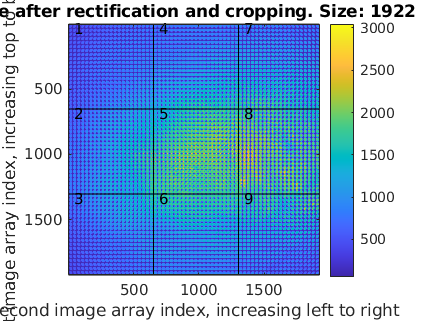

{"location":[[1,1],[651,651]],"size":[651,651],"raw_cut":[[39,721],[43,725]],"raw_cut_xCenter":341.18709677419355,"raw_cut_yCenter":341.18709677419349}
{"location":[[652,1],[1302,651]],"size":[651,651],"raw_cut":[[694,1377],[43,725]],"raw_cut_xCenter":341.18709677419355,"raw_cut_yCenter":341.18709677419349}
{"location":[[1303,1],[1922,651]],"size":[620,651],"raw_cut":[[1350,2001],[43,725]],"raw_cut_xCenter":341.18709677419355,"raw_cut_yCenter":309.98709677419356}
{"location":[[1,652],[651,1302]],"size":[651,651],"raw_cut":[[39,721],[698,1381]],"raw_cut_xCenter":341.18709677419349,"raw_cut_yCenter":341.18709677419349}
{"location":[[652,652],[1302,1302]],"size":[651,651],"raw_cut":[[694,1377],[698,1381]],"raw_cut_xCenter":341.18709677419349,"raw_cut_yCenter":341.18709677419349}
{"location":[[1303,652],[1922,1302]],"size":[620,651],"raw_cut":[[1350,2001],[698,1381]],"raw_cut_xCenter":341.18709677419349,"raw_cut_yCenter":309.98709677419356}
{"location":[[1,1303],[651,1922]],"size":[651,620

Elapsed time is 3.765628 seconds.
Elapsed time is 0.259615 seconds.


Error using corr (line 91)
Requires a data matrix X.

Error in motion_metrics (line 81)
        cY = corr(Yr,mYr);

Error in motion_correctio

tic;
mesolf(SIin);

% job = batch(c, @mesolf, 0, {SIin}) % Runs in cluster
toc  % elapsed time: 1012 seconds

Expected output can be downloaded here:

[https://zenodo.org/record/7306113/files/mesolf_demo_dset_output.zip?download=1](https://zenodo.org/record/7306113/files/mesolf_demo_dset_output.zip?download=1) (500 MB)

Load MesoLF final result for inspection

SO = load(fullfile(SIin.outdir, 'after_filter_final_temporal_result.mat'));

Estimate SNR of neuronal traces, fit baseline, normalize to noise level

traces = SO.global_T_filtered;
noise_std = [];
pp = [];
baseline = [];
noise = zeros(size(traces));
traces_filt = zeros(size(traces));
baseline_ts = zeros(size(traces));
traces_prctlfilt = zeros(size(traces));
for k = 1 : size(traces,1)
    if mod(k, 100) == 0
        fprintf('%i ', k);
    end
    trace = traces(k, :);
    hh = fft([trace flip(trace)]);
    hh(2 : 7) = 0;
    hh(end-5 : end) = 0;
    hh = ifft(hh);
    trace = hh(1 : length(hh)/2);
    
    %trace = zscore(trace);
    noise(k,:) = smooth(trace, 5)' - trace;
    noise_std(k) = std(noise(k,:));
    %baseline(k) = prctile(smooth(traces_hipass(k, :), 8), 25);
    traces_prctlfilt(k,:) = running_percentile(traces(k,:), 100, 5)';
    baseline_ts(k,:) = sgolayfilt(traces_prctlfilt(k,:), 4, 401);
    pp(k) = (max(smooth(trace)) - min(smooth(trace))) / noise_std(k);
    traces_filt(k, :) = trace;
end

100 200 300 400 500 600 

[~, n] = sort(-pp);
SO.snr_sort_ixs = n;
SO.snrs = pp;
SO.ts_noisenorm = (traces - baseline_ts) ./ (noise_std');

Fit each SNR-scaled trace with the "foopsie" auto-regressive model

First, find good values for g and lam by inspection of fit to highest-SNR trace

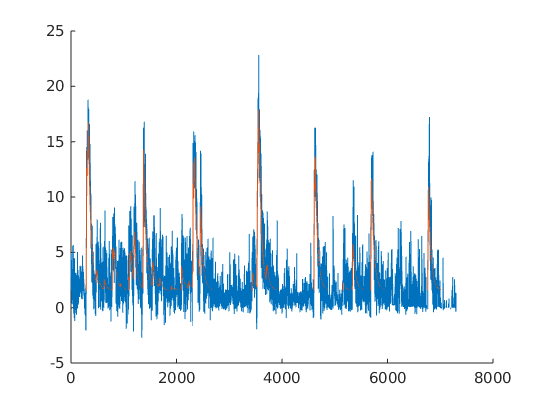

SO.ts_noisenorm_snrsort = SO.ts_noisenorm(SO.snr_sort_ixs, :);
y = SO.ts_noisenorm(1, :);

g = 0.97;  % Parameter of the AR(1) process that models the fluorescence. Higher is slower
lam = 50;  % sparsity
optimize_b = true;
optimize_g = 5;
[c, s, b, g, ~] = foopsi_oasisAR1(y, g, lam, optimize_b, optimize_g);

figure;
hold on;
plot(y);
plot(c + b);
hold off;

Next, fit all traces with fixed g and lam, but re-optimize baseline

for i=1:size(SO.ts_noisenorm,1)
    if mod(i, 100) == 0
        fprintf('%i ', i);
    end
    y = SO.ts_noisenorm(i, :);
    optimize_b = true;
    optimize_g = 0;
    [c, s, b, g, ~] = foopsi_oasisAR1(y, g, lam, optimize_b, optimize_g);
    SO.ts_noisenorm_c(i,:) = c;
    SO.ts_noisenorm_s(i,:) = s;
    SO.ts_noisenorm_b(i) = b;
end

100 200 300 400 500 600 

Stacked line plot of raw and denoised traces, showing top 100 traces in SNR

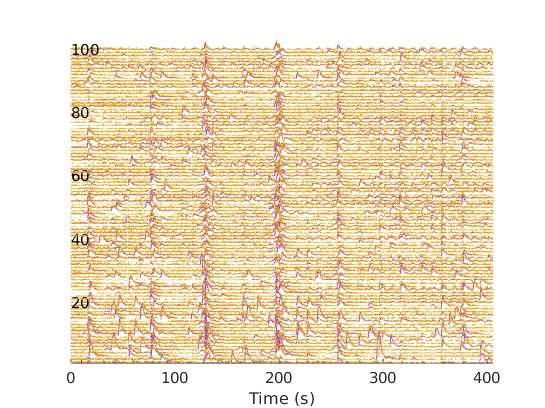

sel_t = 1:size(SO.ts_noisenorm,2);
ts = SO.ts_noisenorm(:, sel_t);
ts_dn = bsxfun(@plus, SO.ts_noisenorm_c, SO.ts_noisenorm_b');
t0 = 0;
t1 = size(ts,2) / SIin.frameRate;
frames = (t0 * SIin.frameRate) + 1 : t1 * SIin.frameRate;
ts = ts(:, frames);
ts_dn = ts_dn(:, frames);

y_shift = 0.9 * abs(prctile(ts(:), 99.0));
sel = SO.snr_sort_ixs;
s0 = 1;
s1 = 100;
sel = sel(s0:s1);
nixs = 1:size(ts,1);
sel_nixs = nixs(sel);

h = 278/360;
s = 0.7;
hsv_dn = [h s .8; h s .8; h s .8; h s .8; h s .8];
h = 42/360;
s = .83;
hsv = [h s .9; h s .9; h s .9; h s .9; h s .9];
colororder = hsv2rgb(hsv);
colororder_dn = hsv2rgb(hsv_dn);

figure;
for n_ix = 1:numel(sel_nixs)
    if n_ix == 1
        hold on
    end
    ax = gca();
    loop_ts = ts(sel_nixs(n_ix),:);
    loop_ts_dn = ts_dn(sel_nixs(n_ix),:);
    t = frames / SIin.frameRate;
    plot(t, squeeze(loop_ts) + y_shift*(n_ix-1), 'Color', colororder(mod(n_ix, 5) + 1,:), 'LineWidth', 0.2);
    plot(t, squeeze(loop_ts_dn) + y_shift*(n_ix-1), 'Color', colororder_dn(mod(n_ix, 5) + 1,:), 'LineWidth', 0.4);
    if mod(n_ix, 20) == 0
        text(t0 * 0.9, y_shift*(n_ix-1), num2str(n_ix));
    end
end
line([10 10], [0 10],'Color',[1 0 0]);
xlabel('Time (s)');
ax = gca;
box off;
ax.YAxis.Visible = 'off';   % remove y-axis
xlim([t0 t1]);
ylim([0 y_shift * (numel(sel_nixs) + 5)]);
yticks([]);
hold off;